
clear;clc;
file = 'Douglas-proj.xls';
nsmooth=8;
Data = xlsread(file);
Absent = (Data(1:70));
Present = (Data(71:end));
fit_x = linspace(0,10,130);
sorted = sortrows(Data, 1, 'descend');
%15
xi = 0:.05:5;
xx=0:0.05:200;
[F_Absent]=ksdensity(Absent,xi);
[F_Present]=ksdensity(Present,xi);
[status,sheets] = xlsfinfo(file);%shows that 3 sheets exist
% the command to read the data
[A,names,raw] =xlsread(file);% reads the first sheet only
LN=length(names); % number of columns with names
A; % data only
names; % headers
raw; % headers and data
Abs=A(1:70);% get the first data set
Prs=A(71:end);  % get the second data set
% Abs and Prs are of different lengths. Because of this, Prs contains NaN
Prs=Prs(~isnan(Prs)); % suppress the NaN


% Rayleigh is best fit for Absent; Gamma best for Present; 

%Absent - Take the lowest chi2stat (lowest fit)
[parGA] = fitdist(Absent, 'gamma');
[hha, pga, HAstats] = chi2gof(Absent,'CDF',parGA);
f_gamma_Absent = pdf('gamma', xi, parGA.a,parGA.b);


[parWA] = fitdist(Absent, 'Weibull');
[hwa, pwa, WAstats] = chi2gof(Absent,'CDF',parWA);
f_weibull_Absent = pdf('Weibull', xi, parWA.A,parWA.B);

[parNA] = fitdist(Absent, 'Nakagami');
[hna, pna, NAstats] = chi2gof(Absent,'CDF',parNA);
f_nakagami_Absent = pdf('Nakagami', xi, parNA.mu,parNA.omega);


[parRA] = fitdist(Absent, 'Rician');
[hra, pra, RAstats] = chi2gof(Absent,'CDF',parRA);
f_rician_Absent = pdf('Rician', xi, parRA.s,parRA.sigma);


[parRayA] = fitdist(Absent, 'Rayleigh');
[hraya, praya, RayAstats] = chi2gof(Absent,'CDF',parRayA);
f_rayleigh_Absent = pdf('Rayleigh', xi, parRayA.b);

fits = ["Gamma"; "Weibull"; "Nakagami"; "Rician";"Rayleigh"];

chi_squared_stat= [HAstats.chi2stat; WAstats.chi2stat; NAstats.chi2stat; RAstats.chi2stat;RayAstats.chi2stat];
pVals = [pga;pwa;pna;pra;praya];
hs = [hha;hwa;hna;hra;hraya];
DoF = [HAstats.df; WAstats.df; NAstats.df; RAstats.df;NAstats.df];
T = table(hs, DoF, chi_squared_stat, pVals, 'RowNames', fits)

T = 5×4 table
                hs    DoF    chi_squared_stat     pVals 
                __    ___    ________________    _______

    Gamma       0      4          6.1112           0.191
    Weibull     0      4          4.6979         0.31972
    Nakagami    0      4           4.811         0.30724
    Rician      0      4          5.0291         0.28432
    Rayleigh    0      4          5.0282         0.41245


bestFitAbs = fits(find(pVals== max(pVals)));
disp('Best fit for absent data: '+ bestFitAbs)

Best fit for absent data: Rayleigh



%Present - Take the lowest chi2stat (lowest fit)

[parGP] = fitdist(Present, 'gamma');
[hgp, pgp, HPstats] = chi2gof(Present,'CDF',parGP);
f_gamma_Present = pdf('gamma', xi, parGP.a,parGP.b);


[parWP] = fitdist(Present, 'Weibull');
[hwp, pwp, WPstats] = chi2gof(Present,'CDF',parWP);
f_weibull_Present = pdf('Weibull', xi, parWP.A,parWP.B);


[parNP] = fitdist(Present, 'Nakagami');
[hnp, pnp, NPstats] = chi2gof(Present,'CDF',parNP);
f_nakagami_Present = pdf('Nakagami', xi, parNP.mu,parNP.omega);


[parRP] = fitdist(Present, 'Rician');
[hrp, prp, RPstats] = chi2gof(Present,'CDF',parRP);
f_rician_Present = pdf('rician', xi, parRP.s,parRP.sigma);


[parRayP] = fitdist(Present, 'Rayleigh');
[hrayp, prayp, RayPstats] = chi2gof(Present,'CDF',parRayP);
f_rayleigh_Present = pdf('Rayleigh', xi, parRayP.b);


chi_squared_stat= [HPstats.chi2stat;WPstats.chi2stat; NPstats.chi2stat; RPstats.chi2stat; RayPstats.chi2stat];


pVals = [pgp;pwp;pnp;prp;prayp];
hs = [hgp;hwp;hnp;hrp;hrayp];
DoF = [HPstats.df; WPstats.df; NPstats.df; RPstats.df;RayPstats.df];
T2 = table(hs, DoF, chi_squared_stat, pVals, 'RowNames', fits)

T2 = 5×4 table
                hs    DoF    chi_squared_stat      pVals   
                __    ___    ________________    __________

    Gamma       0      3          2.0569            0.56068
    Weibull     0      3          2.7903             0.4251
    Nakagami    0      3           2.063            0.55943
    Rician      0      3          2.3429            0.50435
    Rayleigh    1      4          29.422         6.4155e-06


bestFitPres = fits(find(pVals== max(pVals)));
disp('Best fit for present data: '+ bestFitPres)

Best fit for present data: Gamma




% ROC Curve
N0=length(Absent);
N1=length(Present);
dat=[Absent;Present];
resp=[zeros(N0,1);ones(N1,1)];
[pf,pd,T,AUC,OPTOCPT]=perfcurve(resp,dat,1);
AOC = calculateROCarea(resp,dat) %Area under ROC Curve

AOC = 0.8267

A1 = AOC/(2-AOC);
A2 = 2 * AOC^2/(1+AOC);
Std = sqrt((AOC*(1-AOC) + (N1-1)*(A1-AOC^2) + (N0-1)*(A2-AOC^2))/(N0*N1));
areaROC=0.5+polyarea(pf,pd)

areaROC = 0.8267



%ROC
% Change parNA
F_Gamma = cdf(bestFitAbs,xx,parRayA.b); 
% Change parNA 
F_Gamma2 = cdf(bestFitPres,xx,parGP.a,parGP.b);
PF_gamma = 1 - F_Gamma;
PD_gamma = 1 - F_Gamma2;
tArea = polyarea(PF_gamma,PD_gamma)+0.5

tArea = 0.8232

N3 = length(PF_gamma);
N4 = length(PD_gamma);
A3 = tArea/(2-tArea);
A4 = 2 * tArea^2/(1+tArea);

Stdtest = sqrt((tArea*(1-tArea) + (N4-1)*(A3-tArea^2) + (N3-1)*(A4-tArea^2))/(N3*N4))

Stdtest = 0.0047

%ROC EDIT % Gamma Distribution from Part

parGamma_0 = fitdist(Absent,'Rayleigh');
pdfGamma_0 = pdf('Rayleigh',fit_x,parGamma_0.b);
cdfGamma_0 = cdf('Rayleigh',fit_x,parGamma_0.b);

parGamma_1 = fitdist(Present,'Gamma');
pdfGamma_1 = pdf('Gamma',fit_x,parGamma_1.a,parGamma_1.b);
cdfGamma_1 = cdf('Gamma',fit_x,parGamma_1.a,parGamma_1.b);

PF_Gamma = 1-cdfGamma_0;
PD_Gamma = 1-cdfGamma_1;

resp_Gamma = [zeros(length(PF_Gamma),1);ones(length(PD_Gamma), 1)];
dat_Gamma = [PF_Gamma';PD_Gamma'];
AOC_Gamma = polyarea(PF_Gamma, PD_Gamma)+0.5

AOC_Gamma = 0.8230

dist_g = zeros(130,1);
 for i = 1:130
     dist_g(i, 1) = pdist([0,1;PF_Gamma(i), PD_Gamma(i)],'euclidean'); 
 end
 [opt_dist_g, I_g] = min(dist_g);
 sorted_g = sortrows(dat_Gamma, 1, 'descend');

dist = zeros(130,1);
 for i = 1:130
     dist(i, 1) = pdist([0,1;pf(i), pd(i)],'euclidean'); 
 end
 [opt_dist, I] = min(dist);
 
N3 = length(PF_Gamma);
N4 = length(PD_Gamma);
A3 = AOC_Gamma/(2-AOC_Gamma);
A4 = 2 * AOC_Gamma^2/(1+AOC_Gamma);
 
Az= AOC_Gamma

Az = 0.8230

A1=(Az/(2-Az));
A2=(2*Az^2/(1+Az));

std_AOC_Gamma=sqrt((Az*(1-Az)+(N1-1)*(A1-Az^2)+(N0-1)*(A2-Az^2))/(N1*N0))

std_AOC_Gamma = 0.0377

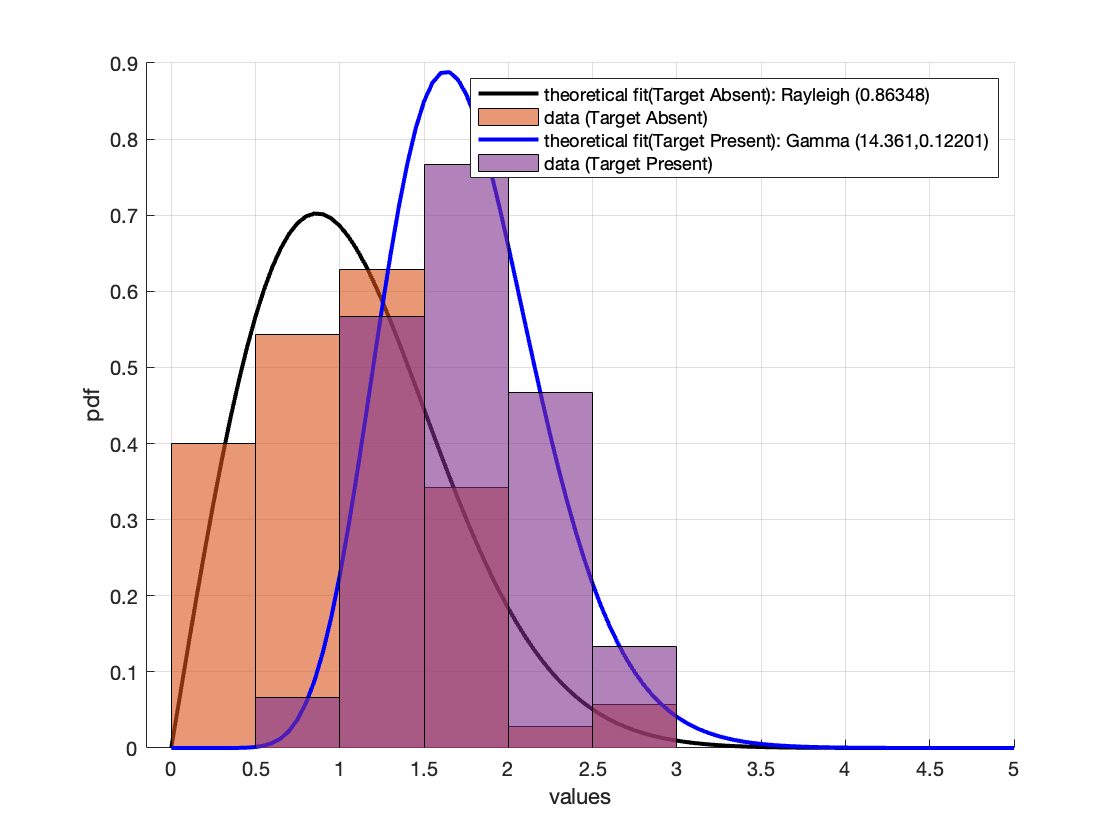



% Bootstrap
btarea = bootstrp(5000,@calculateROCarea,resp,dat); % bootstrap
CI = [prctile(btarea,2.5),prctile(btarea,97.5)]; % Confidence interval
btMean = mean(btarea); % mean of bootstrap
btStd = std(btarea); % standard deviation of bootstrap
TextBT = {['\mu =',num2str(btMean),...
    ', \sigma =',num2str(btStd)],...
    ['95% CI of \mu = [',num2str(CI(1)),',',...
    num2str(CI(2)),']']}; %text used in Bootstrap plot

% Pdf plot                  
fsAbs = [f_gamma_Absent; f_weibull_Absent; f_nakagami_Absent; f_rician_Absent;f_rayleigh_Absent];
fsPres = [f_gamma_Present; f_weibull_Present; f_nakagami_Present; f_rician_Present;f_rayleigh_Present];
bestFAbs =  fsAbs(find(pVals== max(pVals)),:);
bestFPres = fsPres(find(pVals== max(pVals)),:);



figure 
hold on
% title("Theoretical fit vs. Data")
xlabel("values")
ylabel("pdf")

plot(xi, f_rayleigh_Absent, 'k', 'Linewidth', 2) 
%plot(F_Absent)
histogram(Absent,'normalization','pdf');
plot(xi, f_gamma_Present, 'b', 'Linewidth', 2)
%plot(F_Present)
histogram(Present,'normalization','pdf');
grid on
                                                        % Change parNA      % Change parNA
legend(['theoretical fit(Target Absent): Rayleigh (',num2str(parRayA.b), ')'],... % Change parGA and type depending on your best for Absent
    'data (Target Absent)',...
    ['theoretical fit(Target Present): Gamma (',num2str(parGP.a),',', num2str(parGP.b),')'],... % Change parGP and type depending on your best for Present
    'data (Target Present)')
hold off

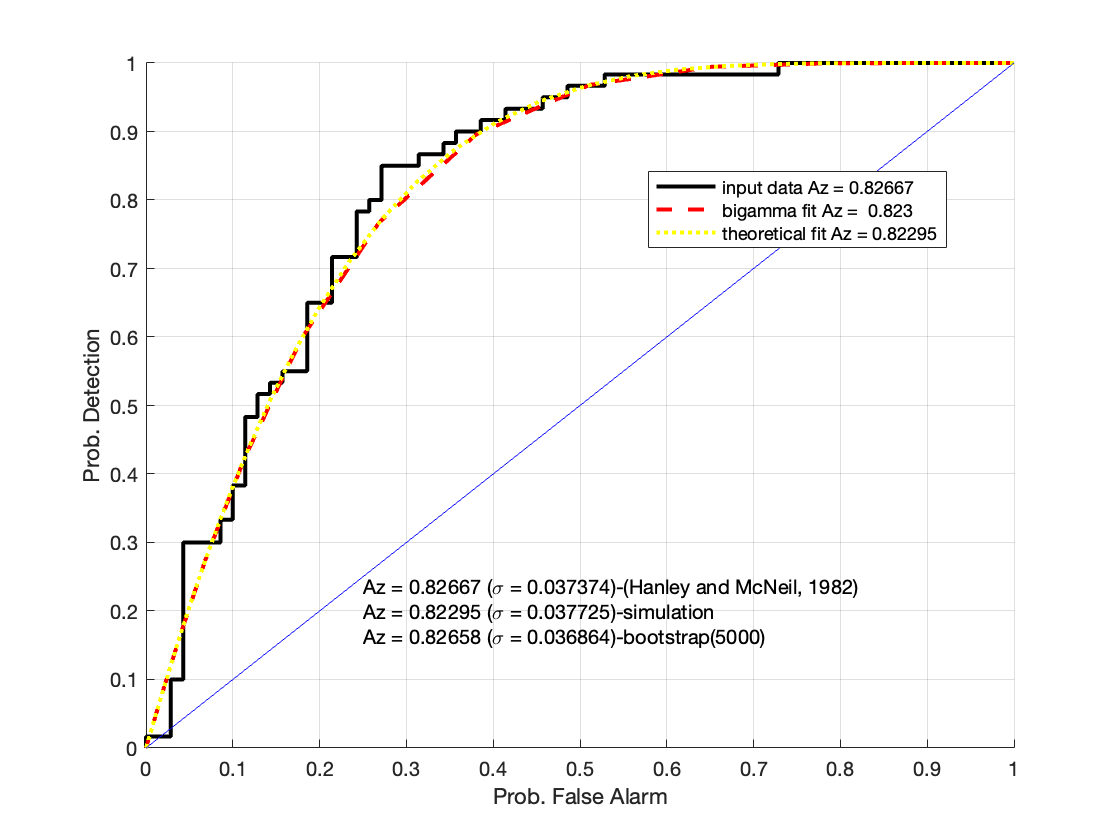


% Plot ROC Curve
figure
hold on
% title(['Az = ', num2str(AOC)])
xlabel("Prob. False Alarm")
ylabel("Prob. Detection")
plot(pf,pd, 'k', 'LineWidth', 2) % black line
Abs=Abs(:);
[parRay]=fitdist(Abs,'Rayleigh');
parRay=fitdist(Abs,'Rayleigh');
ArayAbs=parRay.b; % Rayleigh parameter b;

Prs=Prs(:);
[parGamma]=fitdist(Prs,'Gamma');
parGamma=fitdist(Prs,'Gamma');
aGammaPrs=parGamma.a; % Gamma parameter b;
bGammaPrs=parGamma.b;
grid on

thr=0:0.2:150;
PF=1-cdf('Rayleigh',thr,ArayAbs);
PD=1-cdf('Gamma',thr,aGammaPrs,bGammaPrs);
plot(PF,PD,'r--','linewidth',2)
plot(PF_Gamma,PD_Gamma, 'y:', "linewidth", 2)
plot(0:1,0:1, "b", 'HandleVisibility','off') % blue line
legend(['input data Az = ', num2str(AOC)],['bigamma fit Az =  ',num2str(Az,3)],...
    ['theoretical fit Az = ',num2str(Az)],'Location', 'best')
Text = {['Az = ',num2str(AOC),...
    ' (\sigma = ',num2str(Std),')-(Hanley and McNeil, 1982)'],...
    ['Az = ',num2str(Az),...
    ' (\sigma = ', num2str(std_AOC_Gamma),')-simulation'],...
    ['Az = ',num2str(btMean),...
    ' (\sigma = ',num2str(btStd),')-bootstrap(5000)']};
text(0.25,0.2,Text)
hold off

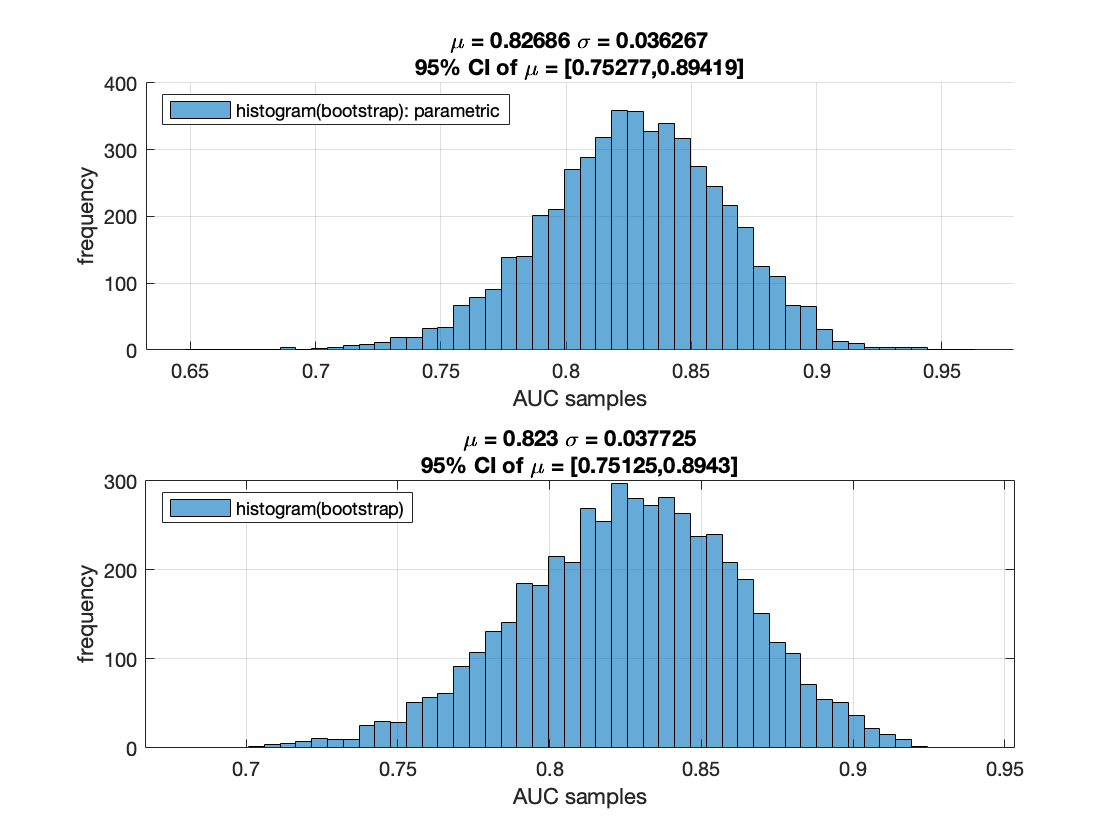


% Bootstrap Plot


%------bootstraping
boot_AUC = bootstrp(5000,@calculateROCarea,resp,Data);
mean_AUC = mean(boot_AUC);
std_AUC = std(boot_AUC);
CI_AUC = [prctile(boot_AUC,2.5),prctile(boot_AUC,97.5)];

%------Plot bootstrap------
subplot(2,1,1)
hold on
Hist_AUC = histogram(boot_AUC,50);
title({strcat("\mu = ",num2str(mean_AUC)," \sigma = ",num2str(std_AUC)), ...
    strcat("95% CI of \mu = [",num2str(CI_AUC(1)),",",num2str(CI_AUC(2)),"]")});
legend("histogram(bootstrap): parametric",'location','northwest');
xlabel('AUC samples')
ylabel('frequency')
grid on 
hold off 
% Bootstrap Plot 2
subplot(2,1,2)

%------bootstraping
boot_AUC1 = bootstrp(5000,@calculateROCarea,resp,Data);
mean_AUC1 = 0.823;
std_AUC1 = std_AOC_Gamma;
CI_AUC1 = [prctile(boot_AUC1,2.5),prctile(boot_AUC1,97.5)];

%------Plot bootstrap------


Hist_AUC = histogram(boot_AUC1,50);
title({strcat("\mu = ",num2str(mean_AUC1)," \sigma = ",num2str(std_AUC1)), ...
    strcat("95% CI of \mu = [",num2str(CI_AUC1(1)),",",num2str(CI_AUC1(2)),"]")});
legend("histogram(bootstrap)",'location','northwest');
xlabel('AUC samples')
ylabel('frequency')
grid on 

function AOC=calculateROCarea(resp,dat)
[pf,pd,T,AUC,OPTOCPT]=perfcurve(resp,dat,1);
AOC=AUC;
end


